# Motor Drive Unit

Copyright 2021 The Mathworks, Inc.

## Open the Model

mdl = "MotorDriveUnitBasic_test_harness";
if not(bdIsLoaded(mdl))
  % A callback function in the model runs the setup script.
  open_system(mdl)
else
  MotorDriveUnitBasic_setup
end

## Load Inputs to Workspace

Input signals are defined as timetable object in a separate MATLAB function. This script only loads it to the workspace.

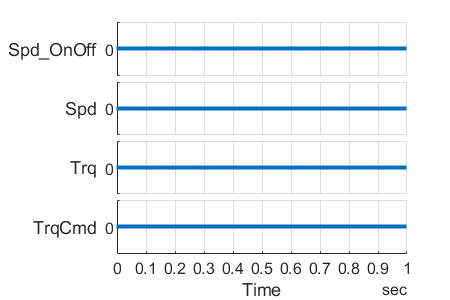

fig = figure;
[inputSignals_MotorDriveUnit, inputBus_MotorDriveUnit, t_end] = ...
  MotorDriveUnitBasic_inputs( "PlotParent",fig, "InputPattern","all_zero" );

## Run Simulation

% Set initial conditions
initial.motorDriveUnit_spd_rpm = 0;

% Override block parameters

% Set simulation input
in = Simulink.SimulationInput(mdl);
in = in.setModelParameter('StopTime',num2str(t_end));

% Run simulation
out = sim(in);

## Visualize Simulation Result

Inpus

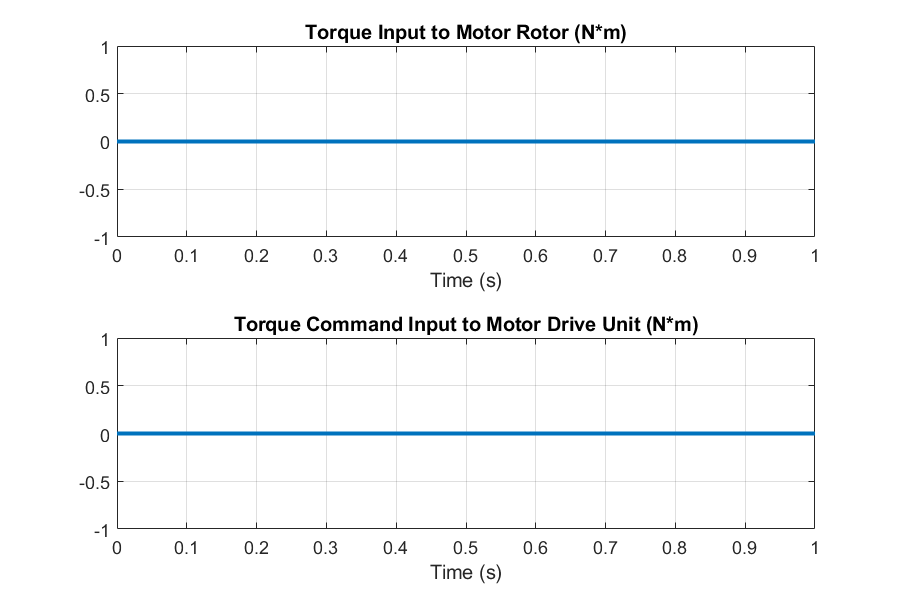

fig = figure;
MotorDriveUnitBasic_plot_result_inputs("PlotParent",fig, "DataSet",out.logsout)

Outputs

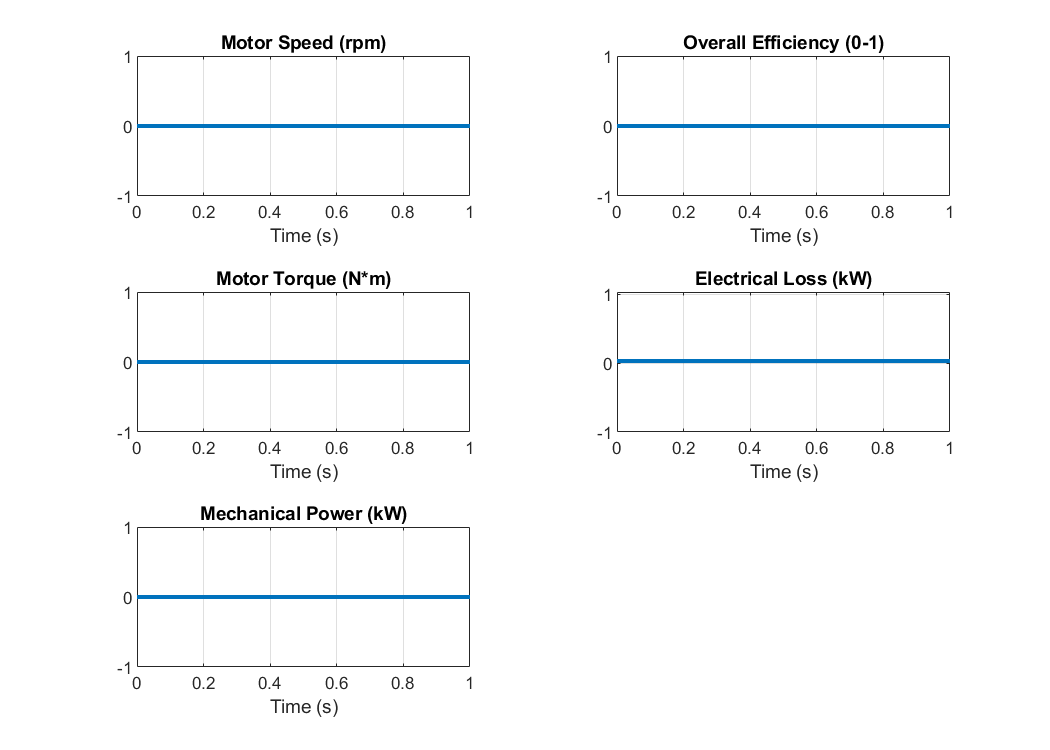

fig = figure;
MotorDriveUnitBasic_plot_result_outputs("PlotParent",fig, "DataSet",out.logsout)